**Experiment - 3                                                                             Date - 9/2/2024**

**Aim :- Realize convolution , correlation, and filtering operations in MATLAB. **

**Laboratory Exercises            **

A) Generate a signal with frequencies of 100 Hz and 250 Hz sampled at 8kHz for a duration of 20ms . Add Gaussian noise into it such that SNR is 5dB . This noisy signal is passed through an LTI system whose impulse response is , 

                                                **h[n] = {0.25,0.5,0.25}**

Comment upon the result for a given LTI System .

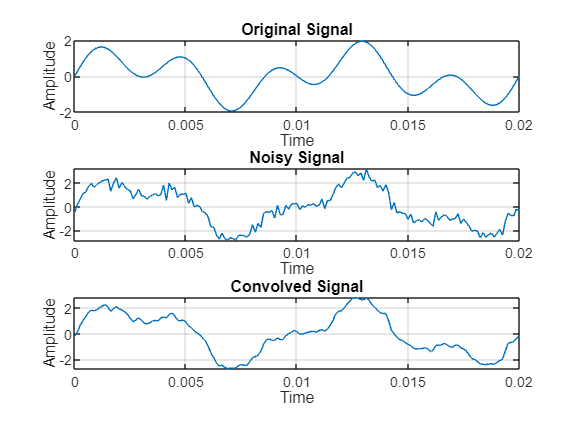

clc ; clear all ; close all ;
%Declaring Original Signal
freq1 = 100 ; samp1 = 8000 ; dur = 1.023 ;

t1 = 0 : (1/samp1) : 0.02 ;
x1 = sin(2*pi*freq1*t1) ;
%subplot(1,3,1) ; plot(t1,x1) ; xlabel("Time") ; ylabel("Amplitude") ; title("Original Signal") ; grid on ;
freq2 = 250 ;
x2 = sin(2*pi*freq2*t1) ;
%subplot(1,2,2) ; plot(t1,x2) ; xlabel("Time") ; ylabel("Amplitude") ; title("Original Signal") ; grid on ;

x = x1 + x2 ;
subplot(3,1,1) ; plot(t1,x) ; xlabel("Time") ; ylabel("Amplitude") ; title("Original Signal") ; grid on ;

%Adding Noise
x3 = x1 + x2 + awgn(x1 , 10) ;
subplot(3,1,2) ; plot(t1,x3) ; xlabel("Time") ; ylabel("Amplitude") ; title("Noisy Signal") ; grid on ;

%h[n]
h = [0.25 0.5 0.25] ;

y1 = conv(x3,h,'same');
subplot(3,1,3) ; plot(t1,y1) ; xlabel("Time") ; ylabel("Amplitude") ; title("Convolved Signal") ; grid on ;

**Comment :-** Here , we achieved a signal similar to the Original Signal after convolution with the Noisy Signal . Increasing the signal to noise ratio we get more clear output in Convolved Signal . 

B) A typical RADAR application estimates delay between transmitted and received signals . Let the sequence x[n] = {3,11,7,0,-1,4,2} is transmitted towards the object . The received sequence is , 

**                                              y[n] = 0.8x[n-2] +w[n]**

Here , w[n] is the Gaussian Noise sequence with zero mean and unity variance . Through cross relation , estimate the delay between transmitted and received sequence to determine Doppler Shift . Repeat this problem for a received sequence 

**                                               z[n] = 0.7x[n-3] +w[n]**

Note :- The cross - relation of given sequences x[n] and y[n] (maximum M samples) is computed as : 

Here , variable l represents the offset or lag and takes the values l = 0 , +-1 , +-2 , ...... , +-(M-1). You can refer the MATLAB function xcorr() for this .

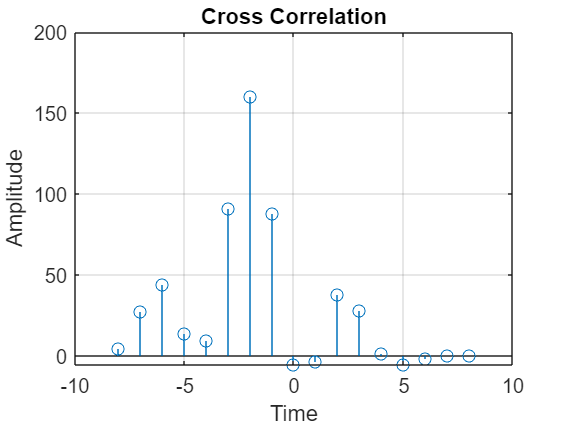

clc ; clear all ; close all ;
xn = [3 11 7 0 -1 4 2]; d = 2 ; xd = [zeros(1,d) xn] ;
n = randn(1,d) ; 

%Declaring y 
y = (0.8 .* xd) ;
for i = 1:d
    y(i) = y(i) + n(i) ;
end

%Plot
[A,l] = xcorr(xn,y) ; stem(l,A) ; grid on ; title("Cross Correlation") ; xlabel("Time") ; ylabel("Amplitude") ;

Fs = 1000000000 ; Ts = (1/Fs) ; taud = 2*Ts ; onced = taud / 2 ; 
%Distance
D = onced * 3 * 100000000 ;
fprintf("The Distance between transmitter and receiver is :- %f ",D); 

The Distance between transmitter and receiver is :- 0.300000 

**Comment :-** Here , we learnt about Radar System , Lag , Distace Calculaticon and using the xcorr() function for finding the crosscorrelation between the input and output signal to calculate distance between the Transmitter and the Receiver.

C) Consider the equation two discrete-time systems characterized by the difference equations : 

**System - 1 **

                y[n] = 0.5x[n] + 0.27x[n-1] + 0.77x[n-2]

**System - 2 **

                y[n] = 0.45x[n]  + 0.5x[n-1] + 0.45x[n-2] + 0.53y[n-1] - 0.46y[n-2]

Otain the output in each case of system given the input is :

                   x[n] = cos(20pin/256) + cos(200pin/256) , with 0 <= n < 299

**Identify the type of filters specified in System-1 and System-2 .**

**Compare the outputs for both systems and identify which system has better characteristics for suppressing the high frequency component of the input signal .  **

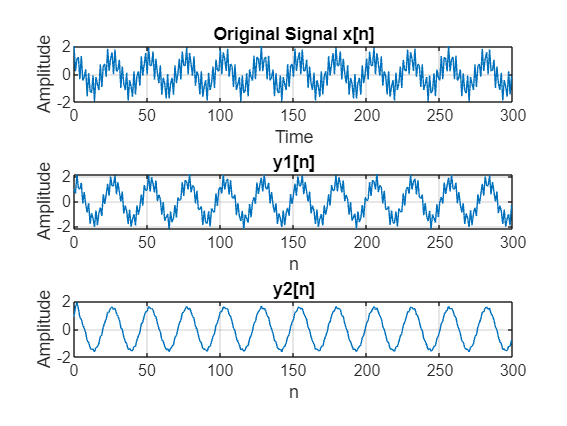

%Type of Filter
clc ; clear all ; close all ;
%Declaring Original Signal
freq1 = (10/256) ; freq2 = (100/256) ; w = 0 : pi/512 : 4*pi ;

t1 = 0 : 1 : 299 ; x1 = cos(2*pi*freq1*t1) + cos(2*pi*freq2*t1) ;
subplot(3,1,1) ; plot(t1,x1) ; xlabel("Time") ; ylabel("Amplitude") ; title("Original Signal x[n]") ; grid on ;

b1  = [0.5 0.27 0.77] ; a1 = [1 0 0] ; y1 = filter(b1,a1,x1) ;
subplot(3,1,2) ; plot(t1,y1) ; grid on ;
title("y1[n]") ; xlabel("n") ; ylabel("Amplitude") ;

b2  = [0.45 0.5 0.45] ; a2 = [1 -0.53 0.46] ; y2 = filter(b2,a2,x1) ;
subplot(3,1,3) ; plot(t1,y2) ; grid on ;
title("y2[n]") ; xlabel("n") ; ylabel("Amplitude") ;

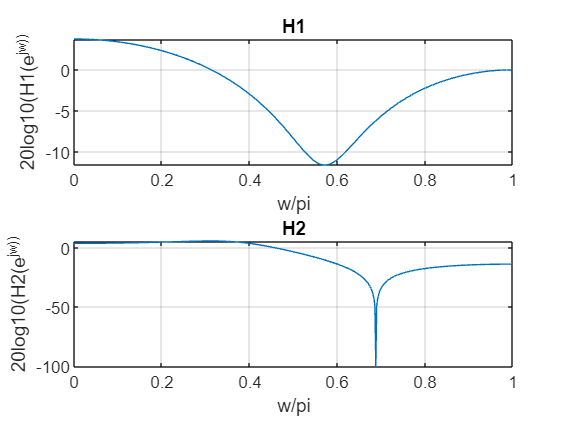

%Comparison
clc ; clear all ; close all ;
figure;
b1  = [0.5 0.27 0.77] ; a1 = [1 0 0] ;
[h1,w] = freqz(b1,a1);
subplot(2,1,1) ; plot(w/pi,20*log10(abs(h1))) ; grid on ;
title("H1") ; xlabel("w/pi") ; ylabel("20log10(H1(e^jw))") ;

b2  = [0.45 0.5 0.45] ; a2 = [1 -0.53 0.46] ;
[h2,w] = freqz(b2,a2);
subplot(2,1,2) ; plot(w/pi,20*log10(abs(h2))) ; grid on ;
title("H2") ; xlabel("w/pi") ; ylabel("20log10(H2(e^jw))") ;

**Comment :- **Here after Mathematical calculations from Graph we conclude that the second signal has better characteristics for suppressing the high frequency component . The power loss in the first system is also high .   

**Conclusion :- In this experiment , we used convolution practically using the xcorr() function , that calculated the crosscorrelation and autocorrelation .**

**We also learnt about the type of filter and how they work on the system .                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                             **